# Fiber Photometry Data Processing

Compiled by Chelsea L. Faber, Nicole Richardson, and Padma Gundapaneni in the Schwartz/Morton research group at the University of Washington. For pre-processing single-site GCaMP + isosbestic fiber photometry recordings using the TDT RZ5P/RZ10x.

Adapted from: 

`Martianova, E., Aronson, S., Proulx, C.D. `[Multi-Fiber Photometry to Record Neural Activity in Freely Moving Animal.](https://www.jove.com/video/60278/multi-fiber-photometry-to-record-neural-activity-freely-moving) `J. Vis. Exp. ``(152), e60278, doi:10.3791/60278 (2019).`

# Your data:

### Import data using TDTbin2mat function. Save struct into a variable called data:

clear; clc;
f = 'G:\Shared drives\Schwartz\Data\Fiber Photometry Experiments\Faber DMH Project\Circadian HFHS Presentation\DMH-4-201108-132008';
data = TDTbin2mat(f);

Found Synapse note file: G:\Shared drives\Schwartz\Data\Fiber Photometry Experiments\Faber DMH Project\Circadian HFHS Presentation\DMH-4-201108-132008\Notes.txt
read from t=0.00s to t=1841.24s


### Take a peek at the photometry signals saved in your data struct. Save them into a new variable, fields:

fields = fieldnames(data.streams);
fields

fields = 3×1 cell array
    {'x470A'}
    {'x405A'}
    {'Fi1r' }


GCAMP = fields{1};
ISOS  = fields{2};

### Plot raw photometry signals:

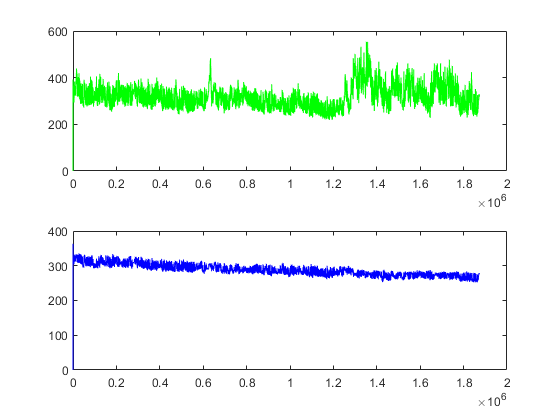

figure
subplot(2,1,1)
plot(data.streams.(GCAMP).data,'g')
subplot(2,1,2)
plot(data.streams.(ISOS).data,'b')

`* Note that these are not truly "raw" signals. Each LED is driven at a different frequency, enabling demodulation of the respective frequencies and dissociation of calcium-dependent and -independent signals. See TDT website for more information on this signal processing.`

# Clean up your data to get ready for analysis:

### (Optional) Trim time from beginning and end of recording:

trimstart = 30;
trimend   = 30;

if trimstart == 0 
    trimstart = 1;
end

if trimend == 0
    trimend = 1;
end

fs     = data.streams.(GCAMP).fs;
start  = trimstart*fs; start = fix(start);
stop   = trimend*fs; stop = fix(stop);

tlength =  length(data.streams.(GCAMP).data);

time       = (1:tlength)/fs; 
Trim_GCAMP = data.streams.(GCAMP).data(start:end-stop);
Trim_ISOS  = data.streams.(ISOS).data(start:end-stop);
trimtime   = time(start:end-stop);

### Down-sample to reduce noise and computing power:

N  =  160;

down_GCAMP  = arrayfun(@(i)...
    mean(Trim_GCAMP(i:i+N-1)),...
    1:N:length(Trim_GCAMP)-N+1);
down_ISOS   = arrayfun(@(i)...
    mean(Trim_ISOS(i:i+N-1)),...
    1:N:length(Trim_ISOS)-N+1);

downtime    = trimtime(1:N:end);
downt       = downtime(1:length(down_GCAMP));

### Smooth data using a moving mean:

smooth_win = 10;
smooth_GCAMP = movmean(down_GCAMP,smooth_win);
smooth_ISOS  = movmean(down_ISOS,smooth_win);

Plot smoothed data.

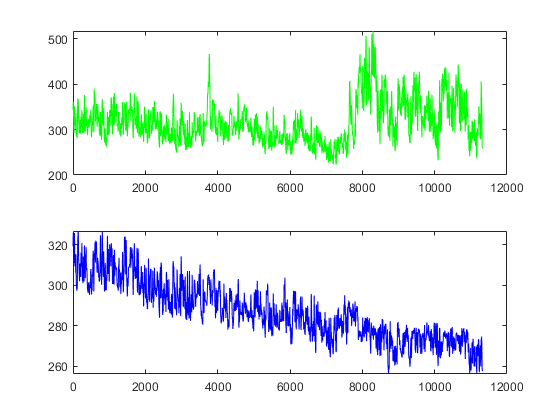

figure
subplot(2,1,1)
plot(smooth_GCAMP,'g')
subplot(2,1,2)
plot(smooth_ISOS,'b')

### Remove slope using airPLS algorithm. 

lambda = 5e13;
order = 2;
wep = 0.1;
p = 0.5;
itermax = 50;

[detrended_GCAMP,base_GCAMP]= airPLS(smooth_GCAMP,lambda,order,wep,p,itermax);
[detrended_ISOS,base_ISOS]= airPLS(smooth_ISOS,lambda,order,wep,p,itermax);

Plot slopes.

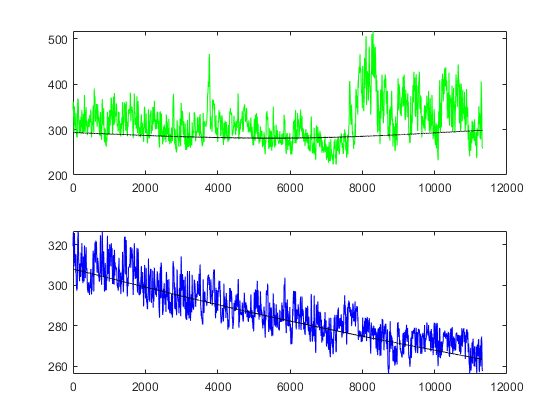

figure
subplot(2,1,1)
plot(smooth_GCAMP,'g')
hold on
plot(base_GCAMP,'k')
hold off
subplot(2,1,2)
plot(smooth_ISOS,'b')
hold on
plot(base_ISOS,'k')
hold off

Plot signals

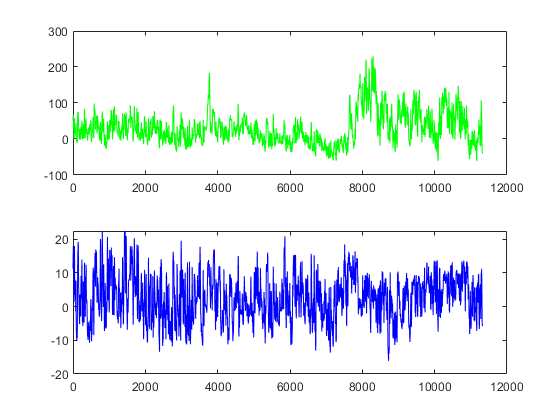

figure
subplot(2,1,1)
plot(detrended_GCAMP,'g')
subplot(2,1,2)
plot(detrended_ISOS,'b')

### Standardize signals

z_GCAMP  = (detrended_GCAMP - median(detrended_GCAMP)) / std(detrended_GCAMP);
z_ISOS   = (detrended_ISOS - median(detrended_ISOS)) / std(detrended_ISOS);

Plot signals

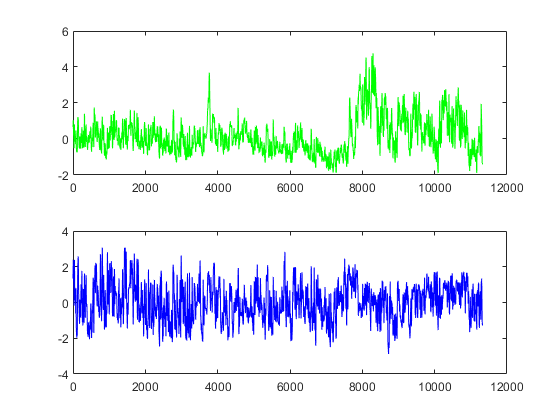

figure
subplot(2,1,1)
plot(z_GCAMP,'g')
subplot(2,1,2)
plot(z_ISOS,'b')

### `Fit reference signal to calcium signal using non negative robust linear regression`

fitdata = fit(z_ISOS',z_GCAMP',fittype('poly1'),'Robust','on');

Plot fit

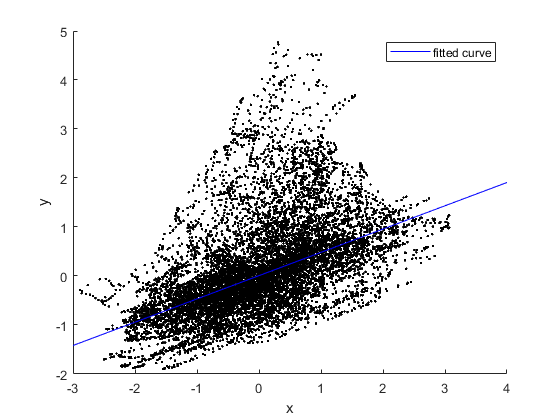

figure
hold on
plot(z_ISOS,z_GCAMP,'k.')
plot(fitdata,'b')
hold off

### `Align reference to signal`

z_ISOS = fitdata(z_ISOS)';

Plot aligned signals

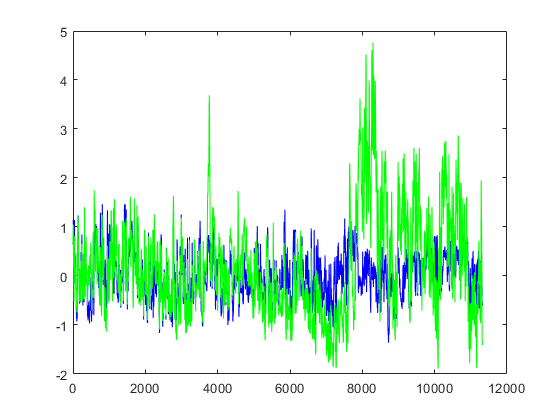

figure
plot(z_ISOS,'b')
hold on
plot(z_GCAMP,'g')
hold off

### `Calculate z-score dF/F`

zdFF = z_GCAMP - z_ISOS;

`Plot z-score dF/F`

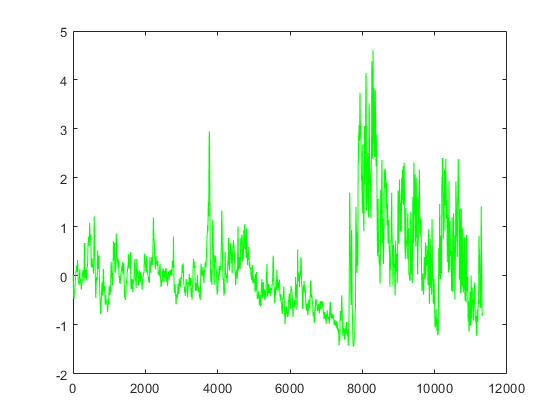

figure
plot(zdFF,'g')